### Init and load torque from excel:

clear
% Increase default font sizes for axes, legend, and text
set(groot, 'DefaultAxesFontSize',   14);
set(groot, 'DefaultLegendFontSize', 14);
set(groot, 'DefaultTextFontSize',   14);

airfoil = Airfoil();
airfoil = airfoil.readPolar(fullfile("Airfoil H polar data","xf-n63015a-il-1000000.csv"))

airfoil =   Airfoil with properties:

            alpha: [143×1 double]
               Cl: [143×1 double]
               Cd: [143×1 double]
               Cm: [143×1 double]
       uppershape: []
       lowershape: []
    upperShapefun: []
    lowerShapefun: []
              x_c: []
           t_cfun: []
              t_c: []
             x_cm: []
               a0: 6.2093
                b: 1.8868e-06
        alphaSPos: 0.2793
        alphaSNeg: -0.2836
              CM0: 6.9641e-09
            Clmax: 1.2465


airfoil = airfoil.readShape(fullfile("Airfoil H XY data","n63015a.dat.txt"))

airfoil =   Airfoil with properties:

            alpha: [143×1 double]
               Cl: [143×1 double]
               Cd: [143×1 double]
               Cm: [143×1 double]
       uppershape: [26×2 double]
       lowershape: [26×2 double]
    upperShapefun: []
    lowerShapefun: []
              x_c: [0 0.0020 0.0040 0.0060 0.0080 0.0100 0.0120 0.0140 0.0160 0.0180 0.0200 0.0220 0.0240 0.0261 0.0281 0.0301 0.0321 0.0341 0.0361 0.0381 0.0401 0.0421 0.0441 0.0461 0.0481 0.0501 0.0521 0.0541 0.0561 0.0581 0.0601 … ] (1×500 double)
           t_cfun: []
              t_c: []
             x_cm: []
               a0: 6.2093
                b: 1.8868e-06
        alphaSPos: 0.2793
        alphaSNeg: -0.2836
              CM0: 6.9641e-09
            Clmax: 1.2465



wing_opt = WingGeometry();
wing_opt.cr = 7.63;
wing_opt.ct = 3.81;
wing_opt.ck = 3.81;
wing_opt.s = 10.68;
wing_opt.yk = wing_opt.s;
wing_opt.Lambdain50 = deg2rad(40);
wing_opt.Lambdaout50 = deg2rad(40);
wing_opt.N = 301;
wing_opt = wing_opt.calcSref();
wing_opt = wing_opt.createStrips();

%load("wing_opt.mat")
load("scr_s0.mat")
load("Farror.mat")
data = load("VTLOAD.mat")

data = struct with fields:
    VTLoad: [1×1 struct]


data.VTLoad.Z = flip(data.VTLoad.Z);
data.VTLoad.S = flip(data.VTLoad.S);
data.VTLoad.M = flip(data.VTLoad.M);
data.VTLoad.T = flip(data.VTLoad.T);


y0 = [-flip(data.VTLoad.Z)'; data.VTLoad.Z(2:end)'];
S0 = -[flip(data.VTLoad.S)'; data.VTLoad.S(2:end)'];
M0 = -[flip(data.VTLoad.M)'; data.VTLoad.M(2:end)'];
tau0 = -[flip(data.VTLoad.T)'; data.VTLoad.T(2:end)'];

M = -interp1(y0, M0, wing_opt.stripy,'spline');
tau = interp1(y0, tau0, wing_opt.stripy,'spline');
S = -interp1(y0, S0, wing_opt.stripy,'spline');


data = load("HTLoad_neg.mat")

data = struct with fields:
    HTLoad_neg: [1×1 struct]


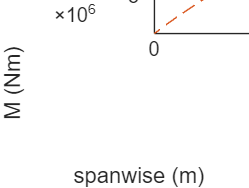

data.HTLoad_neg.Z = flip(data.HTLoad_neg.Z);
data.HTLoad_neg.S = flip(data.HTLoad_neg.S);
data.HTLoad_neg.M = flip(data.HTLoad_neg.M);
data.HTLoad_neg.T = flip(data.HTLoad_neg.T);


y0 = [-flip(data.HTLoad_neg.Z)'; data.HTLoad_neg.Z(2:end)'];
S0 = -[flip(data.HTLoad_neg.S)'; data.HTLoad_neg.S(2:end)'];
M0 = -[flip(data.HTLoad_neg.M)'; data.HTLoad_neg.M(2:end)'];
tau0 = -[flip(data.HTLoad_neg.T)'; data.HTLoad_neg.T(2:end)'];

Mneg = -M;
tauneg = -tau;
Sneg = -S;


figure(1)
clf;
plot(wing_opt.stripy, M)
hold on
plot(wing_opt.stripy, Mneg,'--')
xlabel("spanwise (m)")
ylabel("M (Nm)")
legend("Pos","neg")
xlim([0 wing_opt.b/2])

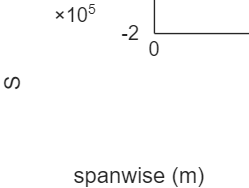


figure(2)
clf;
plot(wing_opt.stripy, S)
hold on
plot(wing_opt.stripy, Sneg,'--')
xlabel("spanwise (m)")
ylabel("S")
legend("Pos","neg")
xlim([0 wing_opt.b/2])

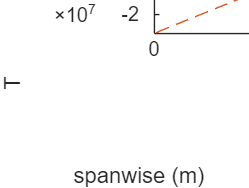



figure(3)
clf;
plot(wing_opt.stripy, tau)
hold on
plot(wing_opt.stripy, tauneg,'--')
xlabel("spanwise (m)")
ylabel("T")
legend("Pos","neg")
xlim([0 wing_opt.b/2])

Material:

Al7068 =material(); %Aluminum 2024 T861
Al7068.E = 71.2e9; %E - 72-75.7 GPa (@23degC is 73)
Al7068.sigma_y = 648e6; %sigma_y - 400-462 MPa (@23degC is 441)
Al7068.G = 28.5e9; %G - 28-29.4 GPa
Al7068.sigma_y_tensile = 683e6;
Al7068.rho = 2850;
Al7068.price = 3.61;

Al2024 = material();
Al2024.E = 72e9; %E - 72-75.7 GPa (@23degC is 73)
Al2024.sigma_y = 400e6; %sigma_y - 400-462 MPa (@23degC is 441)
Al2024.G = 28e9; %G - 28-29.4 GPa
Al2024.sigma_y_tensile = 441e6;
Al2024.rho = 2780;
Al2024.price = 1.88;

sigma_max = 296e6; %maximum allowable stress

## **WingBox geometry (unchanged throughout)**

D = 0.6*6.25;
wb = wingbox();
%define geometry
wb.b2_c = mean(airfoil.uppershape(:,2) - airfoil.lowershape(:,2));
wb.b_c = 0.12;
wb.c_c = 0.7 - wb.b_c;
%wb = wb.calcR();
wb.R_c = wb.b2_c/2;
%define stringers
wb.L = 1;
%show wingbox:
figure(1)
clf;
%wb.drawwithAirfoil(airfoil)
hold on
scatter((wb.b_c + wb.c_c)/2,0,'x')
legend("","","Aerodynamic Centre","","","","","","","","Shear Centre","Interpreter","latex")

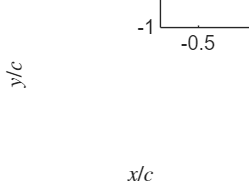

xlabel("$x/c$","Interpreter","latex")
ylabel("$y/c$","Interpreter","latex")
print(gcf, fullfile('images', 'wingbox.png'), '-dpng', '-r300');

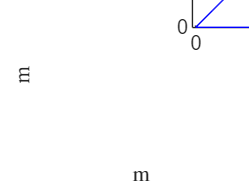


figure(2)
clf;
yline(D/2,'--','LineWidth',2)
hold on
wing_opt.plotWing()
hold on
wb.plotWingBox(wing_opt,D)
axis equal
ylim([0 wing_opt.b/2*1.1])
legend("Fuselage","","","","","","","","","","","","","","","","Wing","","","","","Wing Box","Location","northWest","Interpreter","latex")
xlabel("m","Interpreter","latex")
ylabel("m","Interpreter","latex")
print(gcf, fullfile('images', 'wingboxTopView.png'), '-dpng', '-r300');



wb = wb.calcCellArea(wing_opt);
%define rib spacing
wb.a = ones(1,length(wing_opt.stripy)).*5;
wingidx = find(wing_opt.stripy > D/2); % only consider points on the wing
ywing = wing_opt.stripy(wingidx);

Optimizing skins and spars at the same time

-upper skin: easier to buckle in compressive

-lower skin: easier to yield in tension

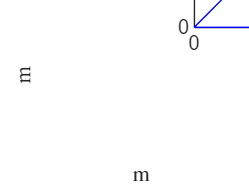

c = wb.c_c .* wing_opt.cn; 
b2 = wb.b2_c .* wing_opt.cn;
N = M ./ c ./ b2;
Nneg = Mneg ./ c ./ b2;

E = Al7068.E;
sigmaY = Al7068.sigma_y;
sigmaYT = Al7068.sigma_y_tensile;

E_L = Al7068.E;
sigmaY_L = Al7068.sigma_y;
sigmaYT_L = Al7068.sigma_y_tensile;

E_r = Al7068.E;
sigmaY_r = Al7068.sigma_y;
sigmaYT_r = Al7068.sigma_y_tensile;

rho_r = Al7068.rho;
rho_Uskin = Al7068.rho;
rho_Lskin = Al7068.rho;
d_hratio = 0.3;

sr_s0_Upper = min(sigmaY./sigma_max,1.4);
[As_bt_vals, ts_t_vals] = findAsbt_ts_for_fb_f0(sr_s0_Upper, 20, 20);

Flist = interpF(As_bt_vals, ts_t_vals);

%crush load
Fcrush = @(M,s,h,t_e,chord,E,I) (M.^2 .* s .* h .* ...
    (t_e) .* chord ./ 2) ./ ...
    (E .* I.^2);

totalM = [];
%loop for each F
wblist = [];
for i = 1:length(Flist)
    if isnan(Flist(i))
        %do nothing
    else
        F = Flist(i);
        As_bt = As_bt_vals(i);
        ts_t = ts_t_vals(i);
        thiswb = wb;
        
        %input upper skin thickness
        t = max(0e-3,N./sigmaY);
        ts = t.*ts_t;
        thiswb.t_Upper = thicknessDoubler(t,wing_opt.stripy,D);
        thiswb.ts_Upper = thicknessDoubler(ts,wing_opt.stripy,D);
        
        %1. upper skin mass
        [thiswb.bs_Upper,thiswb.hs,thiswb.Ks_Upper,thiswb.F,thiswb.sr_s0] = findbs(thiswb.t_Upper, sigmaY, sr_s0_Upper, 3.61, E,As_bt,ts_t,1e-2);
        thiswb.ds = thiswb.hs.*0.3;
        [Mass_Uskin,~,~,thiswb.b1_c] = UskinMass(rho_Uskin, wing_opt, thiswb, wingidx)
        %get rib spacing, becareful with saturation
        thiswb.L = max(N.*E.*(sigmaY./thiswb.F).^(-2), 0.1);
        
        %2. lower skin mass
        %input lower skin thickness
        t_Lower = max(0e-3,N./sigma_max);
        ts_Lower =t_Lower.*ts_t;
        thiswb.t_Lower = thicknessDoubler(t_Lower,wing_opt.stripy,D);
        thiswb.ts_Lower = thicknessDoubler(ts_Lower,wing_opt.stripy,D);
        [thiswb.bs_Lower,thiswb.hs_Lower,thiswb.Ks_Lower,thiswb.F_Lower,thiswb.sr_s0_Lower] = findbs(thiswb.t_Lower, sigmaY_L, sr_s0_Upper, 3.61, E,As_bt,ts_t,1e-2);
        thiswb.ds_Lower = thiswb.hs_Lower.*0.3;
        [Mass_Lskin,~,~,thiswb.b1_c_Lower] = LskinMass(rho_Lskin, wing_opt, thiswb, wingidx)

        %3. rib
        thiswb = thiswb.calcStringerArea();
        thiswb = thiswb.calcStringerArea_Lower();
        h = thiswb.b2_c.*wing_opt.cn;

        t_eff_upper = thiswb.t_Upper + thiswb.As./thiswb.bs_Upper;
        t_eff_upper(isnan(t_eff_upper)) = 0;
        t_eff_lower = thiswb.t_Lower + thiswb.As_Lower./thiswb.bs_Lower;
        t_eff_lower(isnan(t_eff_lower)) = 0;
        chord = wing_opt.cn;
        I_Upper = chord .* (t_eff_upper).^3 ./ 12 + chord .* (t_eff_upper) .* (h./2).^2;
        I_Lower = chord .* (t_eff_lower).^3 ./ 12 + chord .* (t_eff_lower) .* (h./2).^2;

        
        [thiswb.yrib, thiswb.Nrib] = createRibLocationsFromL(thiswb.L, wing_opt, D);
        thiswb = thiswb.mapRibSpacing(wing_opt,D);
        thiswb.L = thiswb.L(152:end);
        thiswb.L = [flip(thiswb.L),NaN,thiswb.L];
        
        %find crush load of all case
        F_pos_upper = abs(Fcrush(M, thiswb.L, h, t_eff_upper, wing_opt.cn, E_r, I_Lower + I_Upper));
        F_neg_upper = abs(Fcrush(Mneg, thiswb.L, h, t_eff_upper, wing_opt.cn, E_r, I_Lower + I_Upper));
        F_pos_lower = abs(Fcrush(M, thiswb.L,h, t_eff_lower, wing_opt.cn, E_r, I_Lower + I_Upper));
        F_neg_lower = abs(Fcrush(Mneg, thiswb.L, h, t_eff_lower, wing_opt.cn, E_r, I_Lower + I_Upper));
        %find the maximum among these
        arrays = {F_pos_upper(wingidx), F_neg_upper(wingidx), F_pos_lower(wingidx), F_neg_lower(wingidx)};
        max_values = cellfun(@(x) max(x(:)), arrays);
        [~, idx] = max(max_values);
        Flarge = arrays{idx};
        
        tr1 = Flarge ./ sigmaY_r ./ wing_opt.cn(wingidx);
        tr2 = (Flarge.*h(wingidx).^2./(3.62.*E_r.*wing_opt.cn(wingidx))).^(1/3);
        tr_max = max(tr1, tr2);
        thiswb.tr = interp1(wing_opt.stripy(wingidx),tr_max,thiswb.yrib(length(thiswb.yrib)/2+1:end));
        thiswb.tr = max(thiswb.tr, 3e-3);
        thiswb.tr = [flip(thiswb.tr); thiswb.tr]
        Mrib = ribMass(thiswb, wing_opt, rho_r)
        
        totalM(i) = Mrib + Mass_Lskin + Mass_Uskin
        wblist = [wblist thiswb];
    end
end

Mass_Uskin = 454.4768

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 … ] (1×301 double)
        t_Lower: []
             tF: []
             tR: []
            c_c: 0.5800
           b1_c: [0.0076 0.0075 0.0075 0.0074 0.0074 0.0073 0.0073 0.0072 0.0072 0.0071 0.0071 0.0071 0.0070 0.0070 0.0069 0.0069 0.0068 0.0068 0.0068 0.0067 0.0067 0.0066 0.0066 0.0066 0.0065 0.0065 0.0064 0.0064 0.0064 0.0063 0.0063 … ] (1×301 double)
     b1_c_Lower: []
       bs_Upper: [0.0288 0.0288 0.0288 0.0288 0.0288 0.0288 0.0288 0.0288 0.0288 0.0288 0.0288 0.0288 0.0288 0.0288 0.0288 0.0288 0.0288 0.0288 0.0288 0.0288 0.0288 0.0288 0.0288 0.0288 0.0288 0.0288 0.0288 0.0288 0.0288 0.0288 0.0288 … ] (1×301 double)
       bs_Lower: [

Mass_Lskin = 919.0012

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 … ] (1×301 double)
        t_Lower: [0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5800
           b1_c: [0.0076 0.0075 0.0075 0.0074 0.0074 0.0073 0.0073 0.0072 0.0072 0.0071 0.0071 0.0071 0.0070 0.0070 0.0069 0.0069 0.0068 0.0068 0.0068 0.0067 0.0067 0.0066 0.0066 0.0066 0.0065 0.0065 0.0064 0.0064 0.0064 0.0063 0.0063 … ] (1×301 double)
     b1_c_Lower: [0.0151 0.0150 0.0149 0.0148 0.0147 0.014

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 … ] (1×301 double)
        t_Lower: [0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5800
           b1_c: [0.0076 0.0075 0.0075 0.0074 0.0074 0.0073 0.0073 0.0072 0.0072 0.0071 0.0071 0.0071 0.0070 0.0070 0.0069 0.0069 0.0068 0.0068 0.0068 0.0067 0.0067 0.0066 0.0066 0.0066 0.0065 0.0065 0.0064 0.0064 0.0064 0.0063 0.0063 … ] (1×301 double)
     b1_c_Lower: [0.0151 0.0150 0.0149 0.0148 0.0147 0.014

Mrib = 2.2061e+03

totalM = 1.0e+03 *

         0         0         0         0         0         0    3.5796


Mass_Uskin = 479.6637

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 … ] (1×301 double)
        t_Lower: []
             tF: []
             tR: []
            c_c: 0.5800
           b1_c: [0.0074 0.0074 0.0073 0.0073 0.0072 0.0072 0.0072 0.0071 0.0071 0.0070 0.0070 0.0069 0.0069 0.0068 0.0068 0.0068 0.0067 0.0067 0.0066 0.0066 0.0066 0.0065 0.0065 0.0065 0.0064 0.0064 0.0063 0.0063 0.0063 0.0062 0.0062 … ] (1×301 double)
     b1_c_Lower: []
       bs_Upper: [0.0284 0.0284 0.0284 0.0284 0.0284 0.0284 0.0284 0.0284 0.0284 0.0284 0.0284 0.0284 0.0284 0.0284 0.0284 0.0284 0.0284 0.0284 0.0284 0.0284 0.0284 0.0284 0.0284 0.0284 0.0284 0.0284 0.0284 0.0284 0.0284 0.0284 0.0284 … ] (1×301 double)
       bs_Lower: [

Mass_Lskin = 965.1481

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 … ] (1×301 double)
        t_Lower: [0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5800
           b1_c: [0.0074 0.0074 0.0073 0.0073 0.0072 0.0072 0.0072 0.0071 0.0071 0.0070 0.0070 0.0069 0.0069 0.0068 0.0068 0.0068 0.0067 0.0067 0.0066 0.0066 0.0066 0.0065 0.0065 0.0065 0.0064 0.0064 0.0063 0.0063 0.0063 0.0062 0.0062 … ] (1×301 double)
     b1_c_Lower: [0.0149 0.0148 0.0147 0.0146 0.0145 0.014

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 … ] (1×301 double)
        t_Lower: [0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5800
           b1_c: [0.0074 0.0074 0.0073 0.0073 0.0072 0.0072 0.0072 0.0071 0.0071 0.0070 0.0070 0.0069 0.0069 0.0068 0.0068 0.0068 0.0067 0.0067 0.0066 0.0066 0.0066 0.0065 0.0065 0.0065 0.0064 0.0064 0.0063 0.0063 0.0063 0.0062 0.0062 … ] (1×301 double)
     b1_c_Lower: [0.0149 0.0148 0.0147 0.0146 0.0145 0.014

Mrib = 2.2061e+03

totalM = 1.0e+03 *

         0         0         0         0         0         0    3.5796    3.6509


Mass_Uskin = 492.3635

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 … ] (1×301 double)
        t_Lower: []
             tF: []
             tR: []
            c_c: 0.5800
           b1_c: [0.0074 0.0073 0.0073 0.0072 0.0072 0.0071 0.0071 0.0070 0.0070 0.0069 0.0069 0.0068 0.0068 0.0068 0.0067 0.0067 0.0066 0.0066 0.0066 0.0065 0.0065 0.0064 0.0064 0.0064 0.0063 0.0063 0.0063 0.0062 0.0062 0.0062 0.0061 … ] (1×301 double)
     b1_c_Lower: []
       bs_Upper: [0.0280 0.0280 0.0280 0.0280 0.0280 0.0280 0.0280 0.0280 0.0280 0.0280 0.0280 0.0280 0.0280 0.0280 0.0280 0.0280 0.0280 0.0280 0.0280 0.0280 0.0280 0.0280 0.0280 0.0280 0.0280 0.0280 0.0280 0.0280 0.0280 0.0280 0.0280 … ] (1×301 double)
       bs_Lower: [

Mass_Lskin = 988.4162

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 … ] (1×301 double)
        t_Lower: [0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5800
           b1_c: [0.0074 0.0073 0.0073 0.0072 0.0072 0.0071 0.0071 0.0070 0.0070 0.0069 0.0069 0.0068 0.0068 0.0068 0.0067 0.0067 0.0066 0.0066 0.0066 0.0065 0.0065 0.0064 0.0064 0.0064 0.0063 0.0063 0.0063 0.0062 0.0062 0.0062 0.0061 … ] (1×301 double)
     b1_c_Lower: [0.0147 0.0146 0.0145 0.0144 0.0143 0.014

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 … ] (1×301 double)
        t_Lower: [0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5800
           b1_c: [0.0074 0.0073 0.0073 0.0072 0.0072 0.0071 0.0071 0.0070 0.0070 0.0069 0.0069 0.0068 0.0068 0.0068 0.0067 0.0067 0.0066 0.0066 0.0066 0.0065 0.0065 0.0064 0.0064 0.0064 0.0063 0.0063 0.0063 0.0062 0.0062 0.0062 0.0061 … ] (1×301 double)
     b1_c_Lower: [0.0147 0.0146 0.0145 0.0144 0.0143 0.014

Mrib = 2.1777e+03

totalM = 1.0e+03 *

         0         0         0         0         0         0    3.5796    3.6509    3.6585


Mass_Uskin = 531.7114

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 … ] (1×301 double)
        t_Lower: []
             tF: []
             tR: []
            c_c: 0.5800
           b1_c: [0.0073 0.0072 0.0072 0.0071 0.0071 0.0070 0.0070 0.0070 0.0069 0.0069 0.0068 0.0068 0.0067 0.0067 0.0067 0.0066 0.0066 0.0065 0.0065 0.0065 0.0064 0.0064 0.0063 0.0063 0.0063 0.0062 0.0062 0.0062 0.0061 0.0061 0.0061 … ] (1×301 double)
     b1_c_Lower: []
       bs_Upper: [0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 … ] (1×301 double)
       bs_Lower: [

Mass_Lskin = 1.0605e+03

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 … ] (1×301 double)
        t_Lower: [0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5800
           b1_c: [0.0073 0.0072 0.0072 0.0071 0.0071 0.0070 0.0070 0.0070 0.0069 0.0069 0.0068 0.0068 0.0067 0.0067 0.0067 0.0066 0.0066 0.0065 0.0065 0.0065 0.0064 0.0064 0.0063 0.0063 0.0063 0.0062 0.0062 0.0062 0.0061 0.0061 0.0061 … ] (1×301 double)
     b1_c_Lower: [0.0146 0.0145 0.0144 0.0143 0.0142 0.014

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 … ] (1×301 double)
        t_Lower: [0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5800
           b1_c: [0.0073 0.0072 0.0072 0.0071 0.0071 0.0070 0.0070 0.0070 0.0069 0.0069 0.0068 0.0068 0.0067 0.0067 0.0067 0.0066 0.0066 0.0065 0.0065 0.0065 0.0064 0.0064 0.0063 0.0063 0.0063 0.0062 0.0062 0.0062 0.0061 0.0061 0.0061 … ] (1×301 double)
     b1_c_Lower: [0.0146 0.0145 0.0144 0.0143 0.0142 0.014

Mrib = 2.0958e+03

totalM = 1.0e+03 *

         0         0         0         0         0         0    3.5796    3.6509    3.6585    3.6880


Mass_Uskin = 568.9786

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 … ] (1×301 double)
        t_Lower: []
             tF: []
             tR: []
            c_c: 0.5800
           b1_c: [0.0072 0.0072 0.0071 0.0071 0.0070 0.0070 0.0070 0.0069 0.0069 0.0068 0.0068 0.0067 0.0067 0.0067 0.0066 0.0066 0.0065 0.0065 0.0065 0.0064 0.0064 0.0063 0.0063 0.0063 0.0062 0.0062 0.0062 0.0061 0.0061 0.0061 0.0060 … ] (1×301 double)
     b1_c_Lower: []
       bs_Upper: [0.0276 0.0276 0.0276 0.0276 0.0276 0.0276 0.0276 0.0276 0.0276 0.0276 0.0276 0.0276 0.0276 0.0276 0.0276 0.0276 0.0276 0.0276 0.0276 0.0276 0.0276 0.0276 0.0276 0.0276 0.0276 0.0276 0.0276 0.0276 0.0276 0.0276 0.0276 … ] (1×301 double)
       bs_Lower: [

Mass_Lskin = 1.1288e+03

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 … ] (1×301 double)
        t_Lower: [0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5800
           b1_c: [0.0072 0.0072 0.0071 0.0071 0.0070 0.0070 0.0070 0.0069 0.0069 0.0068 0.0068 0.0067 0.0067 0.0067 0.0066 0.0066 0.0065 0.0065 0.0065 0.0064 0.0064 0.0063 0.0063 0.0063 0.0062 0.0062 0.0062 0.0061 0.0061 0.0061 0.0060 … ] (1×301 double)
     b1_c_Lower: [0.0145 0.0144 0.0143 0.0142 0.0141 0.014

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 … ] (1×301 double)
        t_Lower: [0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5800
           b1_c: [0.0072 0.0072 0.0071 0.0071 0.0070 0.0070 0.0070 0.0069 0.0069 0.0068 0.0068 0.0067 0.0067 0.0067 0.0066 0.0066 0.0065 0.0065 0.0065 0.0064 0.0064 0.0063 0.0063 0.0063 0.0062 0.0062 0.0062 0.0061 0.0061 0.0061 0.0060 … ] (1×301 double)
     b1_c_Lower: [0.0145 0.0144 0.0143 0.0142 0.0141 0.014

Mrib = 2.0224e+03

totalM = 1.0e+03 *

         0         0         0         0         0         0    3.5796    3.6509    3.6585    3.6880    3.7202


Mass_Uskin = 587.0126

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 … ] (1×301 double)
        t_Lower: []
             tF: []
             tR: []
            c_c: 0.5800
           b1_c: [0.0072 0.0072 0.0071 0.0071 0.0070 0.0070 0.0069 0.0069 0.0069 0.0068 0.0068 0.0067 0.0067 0.0066 0.0066 0.0066 0.0065 0.0065 0.0064 0.0064 0.0064 0.0063 0.0063 0.0063 0.0062 0.0062 0.0062 0.0061 0.0061 0.0061 0.0060 … ] (1×301 double)
     b1_c_Lower: []
       bs_Upper: [0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 … ] (1×301 double)
       bs_Lower: [

Mass_Lskin = 1.1618e+03

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 … ] (1×301 double)
        t_Lower: [0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5800
           b1_c: [0.0072 0.0072 0.0071 0.0071 0.0070 0.0070 0.0069 0.0069 0.0069 0.0068 0.0068 0.0067 0.0067 0.0066 0.0066 0.0066 0.0065 0.0065 0.0064 0.0064 0.0064 0.0063 0.0063 0.0063 0.0062 0.0062 0.0062 0.0061 0.0061 0.0061 0.0060 … ] (1×301 double)
     b1_c_Lower: [0.0144 0.0144 0.0143 0.0142 0.0141 0.014

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 … ] (1×301 double)
        t_Lower: [0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5800
           b1_c: [0.0072 0.0072 0.0071 0.0071 0.0070 0.0070 0.0069 0.0069 0.0069 0.0068 0.0068 0.0067 0.0067 0.0066 0.0066 0.0066 0.0065 0.0065 0.0064 0.0064 0.0064 0.0063 0.0063 0.0063 0.0062 0.0062 0.0062 0.0061 0.0061 0.0061 0.0060 … ] (1×301 double)
     b1_c_Lower: [0.0144 0.0144 0.0143 0.0142 0.0141 0.014

Mrib = 1.9877e+03

totalM = 1.0e+03 *

         0         0         0         0         0         0    3.5796    3.6509    3.6585    3.6880    3.7202    3.7365


Mass_Uskin = 603.0585

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 … ] (1×301 double)
        t_Lower: []
             tF: []
             tR: []
            c_c: 0.5800
           b1_c: [0.0072 0.0072 0.0071 0.0071 0.0070 0.0070 0.0069 0.0069 0.0069 0.0068 0.0068 0.0067 0.0067 0.0066 0.0066 0.0066 0.0065 0.0065 0.0064 0.0064 0.0064 0.0063 0.0063 0.0063 0.0062 0.0062 0.0062 0.0061 0.0061 0.0060 0.0060 … ] (1×301 double)
     b1_c_Lower: []
       bs_Upper: [0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 … ] (1×301 double)
       bs_Lower: [

Mass_Lskin = 1.1912e+03

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 … ] (1×301 double)
        t_Lower: [0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5800
           b1_c: [0.0072 0.0072 0.0071 0.0071 0.0070 0.0070 0.0069 0.0069 0.0069 0.0068 0.0068 0.0067 0.0067 0.0066 0.0066 0.0066 0.0065 0.0065 0.0064 0.0064 0.0064 0.0063 0.0063 0.0063 0.0062 0.0062 0.0062 0.0061 0.0061 0.0060 0.0060 … ] (1×301 double)
     b1_c_Lower: [0.0144 0.0143 0.0143 0.0142 0.0141 0.014

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 … ] (1×301 double)
        t_Lower: [0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5800
           b1_c: [0.0072 0.0072 0.0071 0.0071 0.0070 0.0070 0.0069 0.0069 0.0069 0.0068 0.0068 0.0067 0.0067 0.0066 0.0066 0.0066 0.0065 0.0065 0.0064 0.0064 0.0064 0.0063 0.0063 0.0063 0.0062 0.0062 0.0062 0.0061 0.0061 0.0060 0.0060 … ] (1×301 double)
     b1_c_Lower: [0.0144 0.0143 0.0143 0.0142 0.0141 0.014

Mrib = 1.9537e+03

totalM = 1.0e+03 *

         0         0         0         0         0         0    3.5796    3.6509    3.6585    3.6880    3.7202    3.7365    3.7480


Mass_Uskin = 634.6131

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 … ] (1×301 double)
        t_Lower: []
             tF: []
             tR: []
            c_c: 0.5800
           b1_c: [0.0072 0.0072 0.0071 0.0071 0.0070 0.0070 0.0069 0.0069 0.0069 0.0068 0.0068 0.0067 0.0067 0.0066 0.0066 0.0066 0.0065 0.0065 0.0064 0.0064 0.0064 0.0063 0.0063 0.0063 0.0062 0.0062 0.0062 0.0061 0.0061 0.0060 0.0060 … ] (1×301 double)
     b1_c_Lower: []
       bs_Upper: [0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 … ] (1×301 double)
       bs_Lower: [

Mass_Lskin = 1.2490e+03

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 … ] (1×301 double)
        t_Lower: [0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5800
           b1_c: [0.0072 0.0072 0.0071 0.0071 0.0070 0.0070 0.0069 0.0069 0.0069 0.0068 0.0068 0.0067 0.0067 0.0066 0.0066 0.0066 0.0065 0.0065 0.0064 0.0064 0.0064 0.0063 0.0063 0.0063 0.0062 0.0062 0.0062 0.0061 0.0061 0.0060 0.0060 … ] (1×301 double)
     b1_c_Lower: [0.0144 0.0143 0.0143 0.0142 0.0141 0.014

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 … ] (1×301 double)
        t_Lower: [0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5800
           b1_c: [0.0072 0.0072 0.0071 0.0071 0.0070 0.0070 0.0069 0.0069 0.0069 0.0068 0.0068 0.0067 0.0067 0.0066 0.0066 0.0066 0.0065 0.0065 0.0064 0.0064 0.0064 0.0063 0.0063 0.0063 0.0062 0.0062 0.0062 0.0061 0.0061 0.0060 0.0060 … ] (1×301 double)
     b1_c_Lower: [0.0144 0.0143 0.0143 0.0142 0.0141 0.014

Mrib = 1.8878e+03

totalM = 1.0e+03 *

         0         0         0         0         0         0    3.5796    3.6509    3.6585    3.6880    3.7202    3.7365    3.7480    3.7715


Mass_Uskin = 660.4521

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 … ] (1×301 double)
        t_Lower: []
             tF: []
             tR: []
            c_c: 0.5800
           b1_c: [0.0072 0.0072 0.0071 0.0071 0.0070 0.0070 0.0069 0.0069 0.0068 0.0068 0.0068 0.0067 0.0067 0.0066 0.0066 0.0066 0.0065 0.0065 0.0064 0.0064 0.0064 0.0063 0.0063 0.0063 0.0062 0.0062 0.0061 0.0061 0.0061 0.0060 0.0060 … ] (1×301 double)
     b1_c_Lower: []
       bs_Upper: [0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 … ] (1×301 double)
       bs_Lower: [

Mass_Lskin = 1.2964e+03

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 … ] (1×301 double)
        t_Lower: [0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5800
           b1_c: [0.0072 0.0072 0.0071 0.0071 0.0070 0.0070 0.0069 0.0069 0.0068 0.0068 0.0068 0.0067 0.0067 0.0066 0.0066 0.0066 0.0065 0.0065 0.0064 0.0064 0.0064 0.0063 0.0063 0.0063 0.0062 0.0062 0.0061 0.0061 0.0061 0.0060 0.0060 … ] (1×301 double)
     b1_c_Lower: [0.0144 0.0143 0.0142 0.0141 0.0141 0.014

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 … ] (1×301 double)
        t_Lower: [0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5800
           b1_c: [0.0072 0.0072 0.0071 0.0071 0.0070 0.0070 0.0069 0.0069 0.0068 0.0068 0.0068 0.0067 0.0067 0.0066 0.0066 0.0066 0.0065 0.0065 0.0064 0.0064 0.0064 0.0063 0.0063 0.0063 0.0062 0.0062 0.0061 0.0061 0.0061 0.0060 0.0060 … ] (1×301 double)
     b1_c_Lower: [0.0144 0.0143 0.0142 0.0141 0.0141 0.014

Mrib = 1.8547e+03

totalM = 1.0e+03 *

         0         0         0         0         0         0    3.5796    3.6509    3.6585    3.6880    3.7202    3.7365    3.7480    3.7715    3.8115


Mass_Uskin = 665.7835

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 … ] (1×301 double)
        t_Lower: []
             tF: []
             tR: []
            c_c: 0.5800
           b1_c: [0.0072 0.0072 0.0071 0.0071 0.0070 0.0070 0.0069 0.0069 0.0068 0.0068 0.0068 0.0067 0.0067 0.0066 0.0066 0.0066 0.0065 0.0065 0.0064 0.0064 0.0064 0.0063 0.0063 0.0063 0.0062 0.0062 0.0061 0.0061 0.0061 0.0060 0.0060 … ] (1×301 double)
     b1_c_Lower: []
       bs_Upper: [0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 … ] (1×301 double)
       bs_Lower: [

Mass_Lskin = 1.3062e+03

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 … ] (1×301 double)
        t_Lower: [0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5800
           b1_c: [0.0072 0.0072 0.0071 0.0071 0.0070 0.0070 0.0069 0.0069 0.0068 0.0068 0.0068 0.0067 0.0067 0.0066 0.0066 0.0066 0.0065 0.0065 0.0064 0.0064 0.0064 0.0063 0.0063 0.0063 0.0062 0.0062 0.0061 0.0061 0.0061 0.0060 0.0060 … ] (1×301 double)
     b1_c_Lower: [0.0144 0.0143 0.0142 0.0141 0.0141 0.014

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 … ] (1×301 double)
        t_Lower: [0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5800
           b1_c: [0.0072 0.0072 0.0071 0.0071 0.0070 0.0070 0.0069 0.0069 0.0068 0.0068 0.0068 0.0067 0.0067 0.0066 0.0066 0.0066 0.0065 0.0065 0.0064 0.0064 0.0064 0.0063 0.0063 0.0063 0.0062 0.0062 0.0061 0.0061 0.0061 0.0060 0.0060 … ] (1×301 double)
     b1_c_Lower: [0.0144 0.0143 0.0142 0.0141 0.0141 0.014

Mrib = 1.8527e+03

totalM = 1.0e+03 *

         0         0         0         0         0         0    3.5796    3.6509    3.6585    3.6880    3.7202    3.7365    3.7480    3.7715    3.8115    3.8246


Mass_Uskin = 699.2832

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 … ] (1×301 double)
        t_Lower: []
             tF: []
             tR: []
            c_c: 0.5800
           b1_c: [0.0072 0.0072 0.0071 0.0071 0.0070 0.0070 0.0069 0.0069 0.0068 0.0068 0.0068 0.0067 0.0067 0.0066 0.0066 0.0066 0.0065 0.0065 0.0064 0.0064 0.0064 0.0063 0.0063 0.0062 0.0062 0.0062 0.0061 0.0061 0.0061 0.0060 0.0060 … ] (1×301 double)
     b1_c_Lower: []
       bs_Upper: [0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 … ] (1×301 double)
       bs_Lower: [

Mass_Lskin = 1.3675e+03

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 … ] (1×301 double)
        t_Lower: [0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5800
           b1_c: [0.0072 0.0072 0.0071 0.0071 0.0070 0.0070 0.0069 0.0069 0.0068 0.0068 0.0068 0.0067 0.0067 0.0066 0.0066 0.0066 0.0065 0.0065 0.0064 0.0064 0.0064 0.0063 0.0063 0.0062 0.0062 0.0062 0.0061 0.0061 0.0061 0.0060 0.0060 … ] (1×301 double)
     b1_c_Lower: [0.0144 0.0143 0.0142 0.0141 0.0140 0.014

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 … ] (1×301 double)
        t_Lower: [0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5800
           b1_c: [0.0072 0.0072 0.0071 0.0071 0.0070 0.0070 0.0069 0.0069 0.0068 0.0068 0.0068 0.0067 0.0067 0.0066 0.0066 0.0066 0.0065 0.0065 0.0064 0.0064 0.0064 0.0063 0.0063 0.0062 0.0062 0.0062 0.0061 0.0061 0.0061 0.0060 0.0060 … ] (1×301 double)
     b1_c_Lower: [0.0144 0.0143 0.0142 0.0141 0.0140 0.014

Mrib = 1.8188e+03

totalM = 1.0e+03 *

         0         0         0         0         0         0    3.5796    3.6509    3.6585    3.6880    3.7202    3.7365    3.7480    3.7715    3.8115    3.8246    3.8856


Mass_Uskin = 729.5517

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 … ] (1×301 double)
        t_Lower: []
             tF: []
             tR: []
            c_c: 0.5800
           b1_c: [0.0072 0.0072 0.0071 0.0071 0.0070 0.0070 0.0069 0.0069 0.0069 0.0068 0.0068 0.0067 0.0067 0.0066 0.0066 0.0066 0.0065 0.0065 0.0064 0.0064 0.0064 0.0063 0.0063 0.0063 0.0062 0.0062 0.0062 0.0061 0.0061 0.0061 0.0060 … ] (1×301 double)
     b1_c_Lower: []
       bs_Upper: [0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 … ] (1×301 double)
       bs_Lower: [

Mass_Lskin = 1.4895e+03

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 … ] (1×301 double)
        t_Lower: [0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5800
           b1_c: [0.0072 0.0072 0.0071 0.0071 0.0070 0.0070 0.0069 0.0069 0.0069 0.0068 0.0068 0.0067 0.0067 0.0066 0.0066 0.0066 0.0065 0.0065 0.0064 0.0064 0.0064 0.0063 0.0063 0.0063 0.0062 0.0062 0.0062 0.0061 0.0061 0.0061 0.0060 … ] (1×301 double)
     b1_c_Lower: [0.0145 0.0144 0.0143 0.0142 0.0141 0.014

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 … ] (1×301 double)
        t_Lower: [0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5800
           b1_c: [0.0072 0.0072 0.0071 0.0071 0.0070 0.0070 0.0069 0.0069 0.0069 0.0068 0.0068 0.0067 0.0067 0.0066 0.0066 0.0066 0.0065 0.0065 0.0064 0.0064 0.0064 0.0063 0.0063 0.0063 0.0062 0.0062 0.0062 0.0061 0.0061 0.0061 0.0060 … ] (1×301 double)
     b1_c_Lower: [0.0145 0.0144 0.0143 0.0142 0.0141 0.014

Mrib = 1.7870e+03

totalM = 1.0e+03 *

         0         0         0         0         0         0    3.5796    3.6509    3.6585    3.6880    3.7202    3.7365    3.7480    3.7715    3.8115    3.8246    3.8856    4.0060


Mass_Uskin = 760.7322

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 … ] (1×301 double)
        t_Lower: []
             tF: []
             tR: []
            c_c: 0.5800
           b1_c: [0.0072 0.0072 0.0071 0.0071 0.0070 0.0070 0.0069 0.0069 0.0069 0.0068 0.0068 0.0067 0.0067 0.0066 0.0066 0.0066 0.0065 0.0065 0.0064 0.0064 0.0064 0.0063 0.0063 0.0063 0.0062 0.0062 0.0062 0.0061 0.0061 0.0061 0.0060 … ] (1×301 double)
     b1_c_Lower: []
       bs_Upper: [0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 … ] (1×301 double)
       bs_Lower: [

Mass_Lskin = 1.5519e+03

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 … ] (1×301 double)
        t_Lower: [0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5800
           b1_c: [0.0072 0.0072 0.0071 0.0071 0.0070 0.0070 0.0069 0.0069 0.0069 0.0068 0.0068 0.0067 0.0067 0.0066 0.0066 0.0066 0.0065 0.0065 0.0064 0.0064 0.0064 0.0063 0.0063 0.0063 0.0062 0.0062 0.0062 0.0061 0.0061 0.0061 0.0060 … ] (1×301 double)
     b1_c_Lower: [0.0144 0.0144 0.0143 0.0142 0.0141 0.014

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 … ] (1×301 double)
        t_Lower: [0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5800
           b1_c: [0.0072 0.0072 0.0071 0.0071 0.0070 0.0070 0.0069 0.0069 0.0069 0.0068 0.0068 0.0067 0.0067 0.0066 0.0066 0.0066 0.0065 0.0065 0.0064 0.0064 0.0064 0.0063 0.0063 0.0063 0.0062 0.0062 0.0062 0.0061 0.0061 0.0061 0.0060 … ] (1×301 double)
     b1_c_Lower: [0.0144 0.0144 0.0143 0.0142 0.0141 0.014

Mrib = 1.7565e+03

totalM = 1.0e+03 *

         0         0         0         0         0         0    3.5796    3.6509    3.6585    3.6880    3.7202    3.7365    3.7480    3.7715    3.8115    3.8246    3.8856    4.0060    4.0692


Mass_Uskin = 778.7026

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 … ] (1×301 double)
        t_Lower: []
             tF: []
             tR: []
            c_c: 0.5800
           b1_c: [0.0072 0.0072 0.0071 0.0071 0.0070 0.0070 0.0069 0.0069 0.0069 0.0068 0.0068 0.0067 0.0067 0.0066 0.0066 0.0066 0.0065 0.0065 0.0064 0.0064 0.0064 0.0063 0.0063 0.0063 0.0062 0.0062 0.0062 0.0061 0.0061 0.0061 0.0060 … ] (1×301 double)
     b1_c_Lower: []
       bs_Upper: [0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 0.0275 … ] (1×301 double)
       bs_Lower: [

Mass_Lskin = 1.5878e+03

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 … ] (1×301 double)
        t_Lower: [0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5800
           b1_c: [0.0072 0.0072 0.0071 0.0071 0.0070 0.0070 0.0069 0.0069 0.0069 0.0068 0.0068 0.0067 0.0067 0.0066 0.0066 0.0066 0.0065 0.0065 0.0064 0.0064 0.0064 0.0063 0.0063 0.0063 0.0062 0.0062 0.0062 0.0061 0.0061 0.0061 0.0060 … ] (1×301 double)
     b1_c_Lower: [0.0144 0.0144 0.0143 0.0142 0.0141 0.014

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 … ] (1×301 double)
        t_Lower: [0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5800
           b1_c: [0.0072 0.0072 0.0071 0.0071 0.0070 0.0070 0.0069 0.0069 0.0069 0.0068 0.0068 0.0067 0.0067 0.0066 0.0066 0.0066 0.0065 0.0065 0.0064 0.0064 0.0064 0.0063 0.0063 0.0063 0.0062 0.0062 0.0062 0.0061 0.0061 0.0061 0.0060 … ] (1×301 double)
     b1_c_Lower: [0.0144 0.0144 0.0143 0.0142 0.0141 0.014

Mrib = 1.7525e+03

totalM = 1.0e+03 *

         0         0         0         0         0         0    3.5796    3.6509    3.6585    3.6880    3.7202    3.7365    3.7480    3.7715    3.8115    3.8246    3.8856    4.0060    4.0692    4.1190


Mass_Uskin = 789.8701

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 … ] (1×301 double)
        t_Lower: []
             tF: []
             tR: []
            c_c: 0.5800
           b1_c: [0.0072 0.0072 0.0071 0.0071 0.0071 0.0070 0.0070 0.0069 0.0069 0.0068 0.0068 0.0067 0.0067 0.0067 0.0066 0.0066 0.0065 0.0065 0.0065 0.0064 0.0064 0.0063 0.0063 0.0063 0.0062 0.0062 0.0062 0.0061 0.0061 0.0061 0.0060 … ] (1×301 double)
     b1_c_Lower: []
       bs_Upper: [0.0276 0.0276 0.0276 0.0276 0.0276 0.0276 0.0276 0.0276 0.0276 0.0276 0.0276 0.0276 0.0276 0.0276 0.0276 0.0276 0.0276 0.0276 0.0276 0.0276 0.0276 0.0276 0.0276 0.0276 0.0276 0.0276 0.0276 0.0276 0.0276 0.0276 0.0276 … ] (1×301 double)
       bs_Lower: [

Mass_Lskin = 1.6521e+03

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 … ] (1×301 double)
        t_Lower: [0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5800
           b1_c: [0.0072 0.0072 0.0071 0.0071 0.0071 0.0070 0.0070 0.0069 0.0069 0.0068 0.0068 0.0067 0.0067 0.0067 0.0066 0.0066 0.0065 0.0065 0.0065 0.0064 0.0064 0.0063 0.0063 0.0063 0.0062 0.0062 0.0062 0.0061 0.0061 0.0061 0.0060 … ] (1×301 double)
     b1_c_Lower: [0.0145 0.0144 0.0143 0.0142 0.0141 0.014

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 … ] (1×301 double)
        t_Lower: [0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5800
           b1_c: [0.0072 0.0072 0.0071 0.0071 0.0071 0.0070 0.0070 0.0069 0.0069 0.0068 0.0068 0.0067 0.0067 0.0067 0.0066 0.0066 0.0065 0.0065 0.0065 0.0064 0.0064 0.0063 0.0063 0.0063 0.0062 0.0062 0.0062 0.0061 0.0061 0.0061 0.0060 … ] (1×301 double)
     b1_c_Lower: [0.0145 0.0144 0.0143 0.0142 0.0141 0.014

Mrib = 1.7272e+03

totalM = 1.0e+03 *

         0         0         0         0         0         0    3.5796    3.6509    3.6585    3.6880    3.7202    3.7365    3.7480    3.7715    3.8115    3.8246    3.8856    4.0060    4.0692    4.1190    4.1692


Mass_Uskin = 814.4908

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 … ] (1×301 double)
        t_Lower: []
             tF: []
             tR: []
            c_c: 0.5800
           b1_c: [0.0073 0.0072 0.0072 0.0071 0.0071 0.0070 0.0070 0.0069 0.0069 0.0069 0.0068 0.0068 0.0067 0.0067 0.0067 0.0066 0.0066 0.0065 0.0065 0.0065 0.0064 0.0064 0.0063 0.0063 0.0063 0.0062 0.0062 0.0062 0.0061 0.0061 0.0061 … ] (1×301 double)
     b1_c_Lower: []
       bs_Upper: [0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 … ] (1×301 double)
       bs_Lower: [

Mass_Lskin = 1.7036e+03

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 … ] (1×301 double)
        t_Lower: [0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5800
           b1_c: [0.0073 0.0072 0.0072 0.0071 0.0071 0.0070 0.0070 0.0069 0.0069 0.0069 0.0068 0.0068 0.0067 0.0067 0.0067 0.0066 0.0066 0.0065 0.0065 0.0065 0.0064 0.0064 0.0063 0.0063 0.0063 0.0062 0.0062 0.0062 0.0061 0.0061 0.0061 … ] (1×301 double)
     b1_c_Lower: [0.0145 0.0144 0.0144 0.0143 0.0142 0.014

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 … ] (1×301 double)
        t_Lower: [0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5800
           b1_c: [0.0073 0.0072 0.0072 0.0071 0.0071 0.0070 0.0070 0.0069 0.0069 0.0069 0.0068 0.0068 0.0067 0.0067 0.0067 0.0066 0.0066 0.0065 0.0065 0.0065 0.0064 0.0064 0.0063 0.0063 0.0063 0.0062 0.0062 0.0062 0.0061 0.0061 0.0061 … ] (1×301 double)
     b1_c_Lower: [0.0145 0.0144 0.0144 0.0143 0.0142 0.014

Mrib = 1.7239e+03

totalM = 1.0e+03 *

         0         0         0         0         0         0    3.5796    3.6509    3.6585    3.6880    3.7202    3.7365    3.7480    3.7715    3.8115    3.8246    3.8856    4.0060    4.0692    4.1190    4.1692    4.2420


Mass_Uskin = 839.9082

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 … ] (1×301 double)
        t_Lower: []
             tF: []
             tR: []
            c_c: 0.5800
           b1_c: [0.0073 0.0072 0.0072 0.0071 0.0071 0.0070 0.0070 0.0070 0.0069 0.0069 0.0068 0.0068 0.0067 0.0067 0.0067 0.0066 0.0066 0.0065 0.0065 0.0065 0.0064 0.0064 0.0063 0.0063 0.0063 0.0062 0.0062 0.0062 0.0061 0.0061 0.0061 … ] (1×301 double)
     b1_c_Lower: []
       bs_Upper: [0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 … ] (1×301 double)
       bs_Lower: [

Mass_Lskin = 1.7568e+03

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 … ] (1×301 double)
        t_Lower: [0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5800
           b1_c: [0.0073 0.0072 0.0072 0.0071 0.0071 0.0070 0.0070 0.0070 0.0069 0.0069 0.0068 0.0068 0.0067 0.0067 0.0067 0.0066 0.0066 0.0065 0.0065 0.0065 0.0064 0.0064 0.0063 0.0063 0.0063 0.0062 0.0062 0.0062 0.0061 0.0061 0.0061 … ] (1×301 double)
     b1_c_Lower: [0.0146 0.0145 0.0144 0.0143 0.0142 0.014

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 … ] (1×301 double)
        t_Lower: [0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5800
           b1_c: [0.0073 0.0072 0.0072 0.0071 0.0071 0.0070 0.0070 0.0070 0.0069 0.0069 0.0068 0.0068 0.0067 0.0067 0.0067 0.0066 0.0066 0.0065 0.0065 0.0065 0.0064 0.0064 0.0063 0.0063 0.0063 0.0062 0.0062 0.0062 0.0061 0.0061 0.0061 … ] (1×301 double)
     b1_c_Lower: [0.0146 0.0145 0.0144 0.0143 0.0142 0.014

Mrib = 1.7198e+03

totalM = 1.0e+03 *

         0         0         0         0         0         0    3.5796    3.6509    3.6585    3.6880    3.7202    3.7365    3.7480    3.7715    3.8115    3.8246    3.8856    4.0060    4.0692    4.1190    4.1692    4.2420    4.3165


Mass_Uskin = 840.9944

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 … ] (1×301 double)
        t_Lower: []
             tF: []
             tR: []
            c_c: 0.5800
           b1_c: [0.0073 0.0072 0.0072 0.0071 0.0071 0.0070 0.0070 0.0070 0.0069 0.0069 0.0068 0.0068 0.0067 0.0067 0.0067 0.0066 0.0066 0.0065 0.0065 0.0065 0.0064 0.0064 0.0063 0.0063 0.0063 0.0062 0.0062 0.0062 0.0061 0.0061 0.0061 … ] (1×301 double)
     b1_c_Lower: []
       bs_Upper: [0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 … ] (1×301 double)
       bs_Lower: [

Mass_Lskin = 1.7590e+03

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 … ] (1×301 double)
        t_Lower: [0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5800
           b1_c: [0.0073 0.0072 0.0072 0.0071 0.0071 0.0070 0.0070 0.0070 0.0069 0.0069 0.0068 0.0068 0.0067 0.0067 0.0067 0.0066 0.0066 0.0065 0.0065 0.0065 0.0064 0.0064 0.0063 0.0063 0.0063 0.0062 0.0062 0.0062 0.0061 0.0061 0.0061 … ] (1×301 double)
     b1_c_Lower: [0.0146 0.0145 0.0144 0.0143 0.0142 0.014

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 … ] (1×301 double)
        t_Lower: [0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5800
           b1_c: [0.0073 0.0072 0.0072 0.0071 0.0071 0.0070 0.0070 0.0070 0.0069 0.0069 0.0068 0.0068 0.0067 0.0067 0.0067 0.0066 0.0066 0.0065 0.0065 0.0065 0.0064 0.0064 0.0063 0.0063 0.0063 0.0062 0.0062 0.0062 0.0061 0.0061 0.0061 … ] (1×301 double)
     b1_c_Lower: [0.0146 0.0145 0.0144 0.0143 0.0142 0.014

Mrib = 1.7198e+03

totalM = 1.0e+03 *

         0         0         0         0         0         0    3.5796    3.6509    3.6585    3.6880    3.7202    3.7365    3.7480    3.7715    3.8115    3.8246    3.8856    4.0060    4.0692    4.1190    4.1692    4.2420    4.3165    4.3198


Mass_Uskin = 865.9683

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 … ] (1×301 double)
        t_Lower: []
             tF: []
             tR: []
            c_c: 0.5800
           b1_c: [0.0073 0.0072 0.0072 0.0071 0.0071 0.0070 0.0070 0.0069 0.0069 0.0069 0.0068 0.0068 0.0067 0.0067 0.0066 0.0066 0.0066 0.0065 0.0065 0.0065 0.0064 0.0064 0.0063 0.0063 0.0063 0.0062 0.0062 0.0062 0.0061 0.0061 0.0061 … ] (1×301 double)
     b1_c_Lower: []
       bs_Upper: [0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 … ] (1×301 double)
       bs_Lower: [

Mass_Lskin = 1.8113e+03

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 … ] (1×301 double)
        t_Lower: [0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5800
           b1_c: [0.0073 0.0072 0.0072 0.0071 0.0071 0.0070 0.0070 0.0069 0.0069 0.0069 0.0068 0.0068 0.0067 0.0067 0.0066 0.0066 0.0066 0.0065 0.0065 0.0065 0.0064 0.0064 0.0063 0.0063 0.0063 0.0062 0.0062 0.0062 0.0061 0.0061 0.0061 … ] (1×301 double)
     b1_c_Lower: [0.0145 0.0144 0.0144 0.0143 0.0142 0.014

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 … ] (1×301 double)
        t_Lower: [0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5800
           b1_c: [0.0073 0.0072 0.0072 0.0071 0.0071 0.0070 0.0070 0.0069 0.0069 0.0069 0.0068 0.0068 0.0067 0.0067 0.0066 0.0066 0.0066 0.0065 0.0065 0.0065 0.0064 0.0064 0.0063 0.0063 0.0063 0.0062 0.0062 0.0062 0.0061 0.0061 0.0061 … ] (1×301 double)
     b1_c_Lower: [0.0145 0.0144 0.0144 0.0143 0.0142 0.014

Mrib = 1.6944e+03

totalM = 1.0e+03 *

         0         0         0         0         0         0    3.5796    3.6509    3.6585    3.6880    3.7202    3.7365    3.7480    3.7715    3.8115    3.8246    3.8856    4.0060    4.0692    4.1190    4.1692    4.2420    4.3165    4.3198    4.3716


Mass_Uskin = 891.3417

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 … ] (1×301 double)
        t_Lower: []
             tF: []
             tR: []
            c_c: 0.5800
           b1_c: [0.0073 0.0072 0.0072 0.0071 0.0071 0.0070 0.0070 0.0069 0.0069 0.0068 0.0068 0.0068 0.0067 0.0067 0.0066 0.0066 0.0066 0.0065 0.0065 0.0064 0.0064 0.0064 0.0063 0.0063 0.0063 0.0062 0.0062 0.0061 0.0061 0.0061 0.0060 … ] (1×301 double)
     b1_c_Lower: []
       bs_Upper: [0.0276 0.0276 0.0276 0.0276 0.0276 0.0276 0.0276 0.0276 0.0276 0.0276 0.0276 0.0276 0.0276 0.0276 0.0276 0.0276 0.0276 0.0276 0.0276 0.0276 0.0276 0.0276 0.0276 0.0276 0.0276 0.0276 0.0276 0.0276 0.0276 0.0276 0.0276 … ] (1×301 double)
       bs_Lower: [

Mass_Lskin = 1.8644e+03

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 … ] (1×301 double)
        t_Lower: [0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5800
           b1_c: [0.0073 0.0072 0.0072 0.0071 0.0071 0.0070 0.0070 0.0069 0.0069 0.0068 0.0068 0.0068 0.0067 0.0067 0.0066 0.0066 0.0066 0.0065 0.0065 0.0064 0.0064 0.0064 0.0063 0.0063 0.0063 0.0062 0.0062 0.0061 0.0061 0.0061 0.0060 … ] (1×301 double)
     b1_c_Lower: [0.0145 0.0144 0.0143 0.0142 0.0141 0.014

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 … ] (1×301 double)
        t_Lower: [0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5800
           b1_c: [0.0073 0.0072 0.0072 0.0071 0.0071 0.0070 0.0070 0.0069 0.0069 0.0068 0.0068 0.0068 0.0067 0.0067 0.0066 0.0066 0.0066 0.0065 0.0065 0.0064 0.0064 0.0064 0.0063 0.0063 0.0063 0.0062 0.0062 0.0061 0.0061 0.0061 0.0060 … ] (1×301 double)
     b1_c_Lower: [0.0145 0.0144 0.0143 0.0142 0.0141 0.014

Mrib = 1.7209e+03

totalM = 1.0e+03 *

         0         0         0         0         0         0    3.5796    3.6509    3.6585    3.6880    3.7202    3.7365    3.7480    3.7715    3.8115    3.8246    3.8856    4.0060    4.0692    4.1190    4.1692    4.2420    4.3165    4.3198    4.3716    4.4766


Mass_Uskin = 896.4680

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 … ] (1×301 double)
        t_Lower: []
             tF: []
             tR: []
            c_c: 0.5800
           b1_c: [0.0073 0.0072 0.0072 0.0071 0.0071 0.0070 0.0070 0.0069 0.0069 0.0069 0.0068 0.0068 0.0067 0.0067 0.0066 0.0066 0.0066 0.0065 0.0065 0.0064 0.0064 0.0064 0.0063 0.0063 0.0063 0.0062 0.0062 0.0062 0.0061 0.0061 0.0061 … ] (1×301 double)
     b1_c_Lower: []
       bs_Upper: [0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 … ] (1×301 double)
       bs_Lower: [

Mass_Lskin = 1.8751e+03

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 … ] (1×301 double)
        t_Lower: [0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5800
           b1_c: [0.0073 0.0072 0.0072 0.0071 0.0071 0.0070 0.0070 0.0069 0.0069 0.0069 0.0068 0.0068 0.0067 0.0067 0.0066 0.0066 0.0066 0.0065 0.0065 0.0064 0.0064 0.0064 0.0063 0.0063 0.0063 0.0062 0.0062 0.0062 0.0061 0.0061 0.0061 … ] (1×301 double)
     b1_c_Lower: [0.0145 0.0144 0.0143 0.0142 0.0142 0.014

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 … ] (1×301 double)
        t_Lower: [0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5800
           b1_c: [0.0073 0.0072 0.0072 0.0071 0.0071 0.0070 0.0070 0.0069 0.0069 0.0069 0.0068 0.0068 0.0067 0.0067 0.0066 0.0066 0.0066 0.0065 0.0065 0.0064 0.0064 0.0064 0.0063 0.0063 0.0063 0.0062 0.0062 0.0062 0.0061 0.0061 0.0061 … ] (1×301 double)
     b1_c_Lower: [0.0145 0.0144 0.0143 0.0142 0.0142 0.014

Mrib = 1.7220e+03

totalM = 1.0e+03 *

         0         0         0         0         0         0    3.5796    3.6509    3.6585    3.6880    3.7202    3.7365    3.7480    3.7715    3.8115    3.8246    3.8856    4.0060    4.0692    4.1190    4.1692    4.2420    4.3165    4.3198    4.3716    4.4766    4.4935


Mass_Uskin = 960.9812

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 … ] (1×301 double)
        t_Lower: []
             tF: []
             tR: []
            c_c: 0.5800
           b1_c: [0.0073 0.0072 0.0072 0.0071 0.0071 0.0070 0.0070 0.0069 0.0069 0.0069 0.0068 0.0068 0.0067 0.0067 0.0066 0.0066 0.0066 0.0065 0.0065 0.0064 0.0064 0.0064 0.0063 0.0063 0.0063 0.0062 0.0062 0.0062 0.0061 0.0061 0.0061 … ] (1×301 double)
     b1_c_Lower: []
       bs_Upper: [0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 0.0277 … ] (1×301 double)
       bs_Lower: [

Mass_Lskin = 1.8996e+03

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 … ] (1×301 double)
        t_Lower: [0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5800
           b1_c: [0.0073 0.0072 0.0072 0.0071 0.0071 0.0070 0.0070 0.0069 0.0069 0.0069 0.0068 0.0068 0.0067 0.0067 0.0066 0.0066 0.0066 0.0065 0.0065 0.0064 0.0064 0.0064 0.0063 0.0063 0.0063 0.0062 0.0062 0.0062 0.0061 0.0061 0.0061 … ] (1×301 double)
     b1_c_Lower: [0.0145 0.0144 0.0143 0.0142 0.0142 0.014

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 … ] (1×301 double)
        t_Lower: [0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5800
           b1_c: [0.0073 0.0072 0.0072 0.0071 0.0071 0.0070 0.0070 0.0069 0.0069 0.0069 0.0068 0.0068 0.0067 0.0067 0.0066 0.0066 0.0066 0.0065 0.0065 0.0064 0.0064 0.0064 0.0063 0.0063 0.0063 0.0062 0.0062 0.0062 0.0061 0.0061 0.0061 … ] (1×301 double)
     b1_c_Lower: [0.0145 0.0144 0.0143 0.0142 0.0142 0.014

Mrib = 1.7220e+03

totalM = 1.0e+03 *

         0         0         0         0         0         0    3.5796    3.6509    3.6585    3.6880    3.7202    3.7365    3.7480    3.7715    3.8115    3.8246    3.8856    4.0060    4.0692    4.1190    4.1692    4.2420    4.3165    4.3198    4.3716    4.4766    4.4935    4.5825


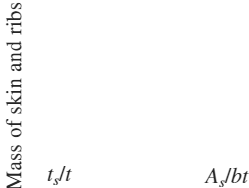

totalM(totalM == 0) = NaN;
[~,minidx] = min(totalM);
%minidx = length(wblist);
wb = wblist(minidx);
As_bt = As_bt_vals(minidx);
ts_t = ts_t_vals(minidx);


[X, Y] = meshgrid(As_bt_vals, ts_t_vals);
Z = repmat(totalM, length(ts_t_vals), 1);  % Replicate totalM along each row
figure(2);
clf;
surf(X, Y, Z);
xlabel('$A_s/bt$',"Interpreter","latex");
ylabel('$t_s/t$',"Interpreter","latex");
zlabel("Mass of skin and ribs (kg)","Interpreter","latex")
print(gcf, fullfile('images_new', 'Optimization.png'), '-dpng', '-r300')

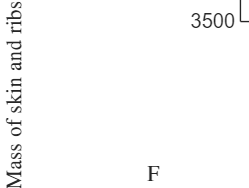


figure(3)
clf;
plot(Flist,totalM)
xlabel("F","Interpreter","latex")
ylabel("Mass of skin and ribs (kg)","Interpreter","latex")
print(gcf, fullfile('images_new', 'MvsF.png'), '-dpng', '-r300')

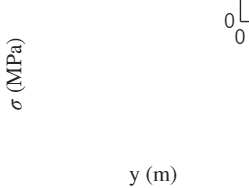



figure(5)
clf;
% Global Buckling: Solid Blue, Thick
sigmaGlobal =  wb.sr_s0.*wb.Ks_Upper.*E.*(wb.t_Upper./(wb.b1_c.*wing_opt.cn)).^2;
plot(wing_opt.stripy(wingidx), sigmaGlobal(wingidx)*1e-6, ...
    'LineStyle', '--', 'Color', [0, 0.4470, 0.7410], 'LineWidth', 2);
hold on;
% Local Buckling: Dashed Orange, Medium
sigmaLocal = wb.F.* sqrt(N.*E./wb.L);
sigmacr_Uskin = sigmaLocal;
plot(wing_opt.stripy(wingidx), sigmaLocal(wingidx).*1e-6, ...
    'LineStyle', '-', 'Color', [0.8500, 0.3250, 0.0980], 'LineWidth', 1.5);
% Compressive Load: Dotted Green, Thick
plot(wing_opt.stripy(wingidx), N(wingidx)./wb.t_Upper(wingidx)*1e-6, ...
    'LineStyle', ':', 'Color', [0.4660, 0.6740, 0.1880], 'LineWidth', 2);
sigma_Uskin = N./wb.t_Upper;
% Tensile Load: Dash-Dot Purple, Medium
plot(wing_opt.stripy(wingidx), -Nneg(wingidx)./wb.t_Upper(wingidx)*1e-6, ...
    'LineStyle', '-.', 'Color', [0.4940, 0.1840, 0.5560], 'LineWidth', 1.5);
% Compressive Yield: Solid Black
yline(sigmaY*1e-6, 'LineStyle', '-', 'Color', 'k', 'LineWidth', 1);
% Tensile Yield: Dashed Black
yline(sigmaYT*1e-6, 'LineStyle', '--', 'Color', 'k', 'LineWidth', 1);

legend("Global Buckling","Local Buckling","Compressive Load","Tensile Load",...
    "Compressive Yield Stress","Tensile Yield Stress", "Interpreter","latex","Location","northwest");
xlabel("y (m)", "Interpreter", "latex");
ylabel("$\sigma$ (MPa)", "Interpreter", "latex");
xlim([0 wing_opt.s]);
ylim([0 1300])
print(gcf, fullfile('images_new', 'UpperStressDiagram.png'), '-dpng', '-r300')



figure(7)
clf;
% Global Buckling: Solid Blue, Thick
sigmaGlobal =  wb.sr_s0_Lower.*wb.Ks_Lower.*E.*(wb.t_Lower./(wb.b1_c_Lower.*wing_opt.cn)).^2;
plot(wing_opt.stripy(wingidx), sigmaGlobal(wingidx)*1e-6, ...
    'LineStyle', '-', 'Color', [0, 0.4470, 0.7410], 'LineWidth', 2);
hold on;
sigmaLocal = wb.F_Lower.*sqrt(-Nneg.*E./wb.L)

sigmaLocal = 1.0e+08 *

         0    0.0350    0.0903    0.1513    0.2174    0.2871    0.3596    0.4343    0.5108    0.5888    0.6680    0.7483    0.8294    0.9113    0.9938    1.0769    1.1603    1.2441    1.3282    1.4125    1.4969    1.5815    1.6661    1.7508    1.8354    1.9199    2.0044    2.0888    2.1731    2.2572    2.3411    2.4248    2.5083    2.5916    2.6747    2.7575    2.8400    2.9222    3.0042    3.0859    3.1672    3.2482    3.3290    3.4093    3.4894    3.5691    3.6485    3.7275    3.8062    3.8845


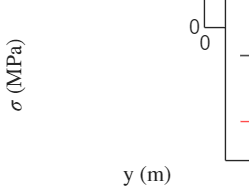

sigmacr_Lskin = sigmaLocal;
% Local Buckling: Dashed Orange, Medium
plot(wing_opt.stripy(wingidx), sigmaLocal(wingidx).*1e-6, ...
    'LineStyle', '--', 'Color', [0.8500, 0.3250, 0.0980], 'LineWidth', 1.5);
% Compressive Load: Dotted Green, Thick
plot(wing_opt.stripy(wingidx), -Nneg(wingidx)./wb.t_Lower(wingidx)*1e-6, ...
    'LineStyle', ':', 'Color', [0.4660, 0.6740, 0.1880], 'LineWidth', 2);
sigma_Lskin = -Nneg./wb.t_Lower;
% Tensile Load: Dash-Dot Purple, Medium
plot(wing_opt.stripy(wingidx), N(wingidx)./wb.t_Lower(wingidx)*1e-6, ...
    'LineStyle', '-.', 'Color', [0.4940, 0.1840, 0.5560], 'LineWidth', 1.5);
% Compressive Yield: Solid Black
yline(sigmaY_L*1e-6, 'LineStyle', '-', 'Color', 'k', 'LineWidth', 1);
% Tensile Yield: Dashed Black
yline(sigmaYT_L*1e-6, 'LineStyle', '--', 'Color', 'k', 'LineWidth', 1);
hold on
yline(sigma_max*1e-6,"r-")
legend("Global Buckling","Local Buckling","Compressive Load","Tensile Load",...
    "Compressive Yield Stress","Tensile Yield Stress","Fatigue tensile stress", "Interpreter","latex","Location","northwest");
xlabel("y (m)", "Interpreter", "latex");
ylabel("$\sigma$ (MPa)", "Interpreter", "latex");
xlim([0 wing_opt.s]);
ylim([0 900])
print(gcf, fullfile('images_new', 'LowerStressDiagram.png'), '-dpng', '-r300')

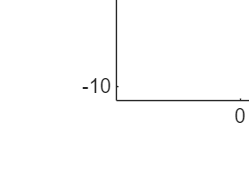



figure(6)
clf;
wing_opt.plotWing
hold on
wb.plotRibs(wing_opt)
hold on
wb.plotWingBox(wing_opt,D)
ylim([0 wing_opt.b/2*1.02])
axis equal
print(gcf, fullfile('images_new', 'RibsVT.png'), '-dpng', '-r300')

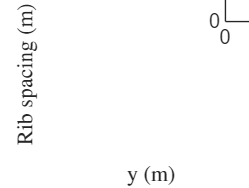


figure(4)
clf;
idealL = max(N.*E.*(sigmaY./wb.F).^(-2), 0);
plot(wing_opt.stripy(wingidx), max(idealL(wingidx),0),'Color', [0 0.4470 0.7410])
hold on
plot(wing_opt.stripy(wingidx), wb.L(wingidx),'LineWidth',1.5)
xlim([0, wing_opt.b/2])
ylim([0 max(wb.L*1.1)])
ylabel("Rib spacing (m)","Interpreter","latex")
xlabel("y (m)","Interpreter","latex")
legend("Ideal","Actual","Interpreter","latex","Location","southwest")
print(gcf, fullfile('images_new', 'RibSpacing.png'), '-dpng', '-r300');

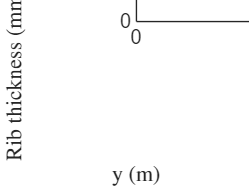


figure(5)
clf;
scatter(wb.yrib, wb.tr*1000,'x')
xlim([0, wing_opt.b/2])
ylim([0 max(wb.tr*1000*1.1)])
ylabel("Rib thickness (mm)","Interpreter","latex")
xlabel("y (m)","Interpreter","latex")
print(gcf, fullfile('images_new', 'RibThicknessVT.png'), '-dpng', '-r300');

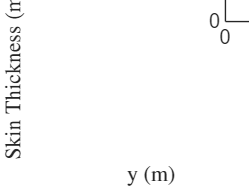


figure(6)
clf;
idealtUp = N./sigmaY;
idealtLow = N./sigma_max;

plot(ywing,idealtUp(wingidx),'r--')
hold on
plot(ywing, wb.t_Upper(wingidx),'r','LineWidth',1.2)
hold on
plot(ywing,idealtLow(wingidx),'b--')
hold on
plot(ywing,wb.t_Lower(wingidx),'b','LineWidth',1.2)
xlim([0, wing_opt.b/2])
ylim([0 0.06])
ylabel("Skin Thickness (m)","Interpreter","latex")
xlabel("y (m)","Interpreter","latex")
legend("Ideal, upper","Actual, upper","Ideal, lower","Actual, lower","Interpreter","latex","Location","southwest")
print(gcf, fullfile('images_new', 'SkinThickness.png'), '-dpng', '-r300');

## **3. Spar buckling analysis(get spar thickness)**

**Web is fixed at top/bottom, SS at sides (web stringers)**

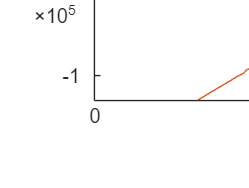

%[t_FS, t_RS] = Sparfun(wb, wing_opt,material,V,T,wbStress)

%for maximum buckling coefficient, let a = h
wb.a = wb.b2_c.*wing_opt.cn;
Ks = 8.1;
E = Al7068.E;

%Use same As/bt and ts/t
%z stringer
figure(1)
clf;
plot(wing_opt.stripy(wingidx), S(wingidx))
hold on
plot(wing_opt.stripy(wingidx), Sneg(wingidx))
xlim([0 wing_opt.b/2])

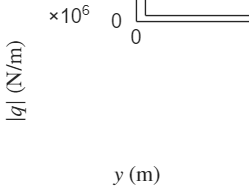


Awb = wb.c_c.*wb.b2_c.*wing_opt.cn.*wing_opt.cn;
hwb = wb.b2_c.*wing_opt.cn;

q = @(S,T,h,A) S./(2*h) + T./(2*A);

qFpos = q(-S,tau,hwb,Awb);
qFneg = q(-Sneg,tau,hwb,Awb);
qRpos = q(-S,-tau,hwb,Awb);
qRneg = q(-Sneg,-tau,hwb,Awb);

figure(2);
clf;

% Define line styles/colors for clarity
front_color = [0, 0.4470, 0.7410];  % Blue for front
rear_color = [0.8500, 0.3250, 0.0980];  % Red for rear
linewidth = 2;  % Thicker lines for visibility

% Plot front (+/-)
plot(wing_opt.stripy(wingidx), abs(qFpos(wingidx)), ...
    'Color', front_color, 'LineStyle', '-', 'LineWidth', linewidth);
hold on;
plot(wing_opt.stripy(wingidx), abs(qFneg(wingidx)), ...
    'Color', front_color, 'LineStyle', '--', 'LineWidth', linewidth);

% Plot rear (+/-)
plot(wing_opt.stripy(wingidx), abs(qRpos(wingidx)), ...
    'Color', rear_color, 'LineStyle', '-', 'LineWidth', linewidth);
plot(wing_opt.stripy(wingidx), abs(qRneg(wingidx)), ...
    'Color', rear_color, 'LineStyle', '--', 'LineWidth', linewidth);

% Formatting
legend("Front, +", "Front, -", "Rear, +", "Rear, -", ...
    'Interpreter', 'latex', 'Location', 'best');
ylabel("$\left| q \right|$ (N/m)", "Interpreter", "latex");
xlabel("$y$ (m)", "Interpreter", "latex");
xlim([0, wing_opt.b/2]);

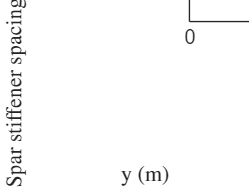

[y_spar_s, N_spar_s] = createRibLocationsFromL(wb.b2_c.*wing_opt.cn, wing_opt, D);
y_wing = wing_opt.stripy;
yrib   = y_spar_s;

% Sort yrib if not already sorted
yrib = sort(yrib);

% Pre-allocate L
L = zeros(size(y_wing));

for i = 1:length(y_wing)
    y_i = y_wing(i);

    % 1) Check if y_i is within [-D/2, D/2]
    if (y_i >= -D/2) && (y_i <= D/2)
        % If in the fuselage region, set L to NaN
        L(i) = NaN;
    else
        % 2) Otherwise, find the adjacent ribs
        k = find(yrib <= y_i, 1, 'last');

        if isempty(k)
            % y_i < yrib(1)
            L(i) = yrib(2) - yrib(1);
        elseif k == length(yrib)
            % y_i >= yrib(end)
            L(i) = yrib(end) - yrib(end-1);
        else
            % y_i lies between yrib(k) and yrib(k+1)
            L(i) = yrib(k+1) - yrib(k);
        end
    end
end

a = L;
wb.a = L;

% Initialize an array to store the indices
sparidx = NaN(size(y_spar_s)); % Use NaN for excluded points

% Loop through each point in y_spar_s
for i = 1:length(y_spar_s)
    % Find the index of the closest point in wing_opt.stripy
    [~, idx] = min(abs(wing_opt.stripy - y_spar_s(i)));
    
    % Check if the corresponding wing_opt.stripy value is within the desired range
    if abs(wing_opt.stripy(idx)) >= D/2
        sparidx(i) = idx; % Store the index if the condition is satisfied
    end
    % Otherwise, sparidx(i) remains NaN (excluded)
end



figure(3)
clf;
plot(wing_opt.stripy(wingidx), wb.b2_c.*wing_opt.cn(wingidx),'LineWidth',1.6)
hold on
scatter(wing_opt.stripy(sparidx), wb.a(sparidx),'x','r')
hold on
plot(wing_opt.stripy(wingidx), wb.a(wingidx),'r')
legend("Ideal $a$ = $h_{wb}$","Stiffener location","Actual $a$", "Interpreter", "latex")
xlabel("y (m)", "Interpreter", "latex")
ylabel("Spar stiffener spacing (m)", "Interpreter", "latex")
xlim([0 wing_opt.b/2])
print(gcf, fullfile('images_new', 'aspar.png'), '-dpng', '-r300');

wb.y_sparS = wing_opt.stripy(sparidx);

q_FS = abs(qFneg);
q_RS = abs(qRpos);

t_FS = (q_FS .* b2 ./ Ks ./ E).^(1/3);%thickness front spar
t_RS = (q_RS .* b2 ./ Ks ./ E).^(1/3);%thickness

tFd = [0.019 0.016 0.011]

tFd =     0.0190    0.0160    0.0110


tRd = [0.02 0.018 0.013]

tRd =     0.0200    0.0180    0.0130



wb.tF = thicknessDoubler(flip(t_FS),wing_opt.stripy,D)

wb =   wingbox with properties:

            t_D: []
        t_Upper: [1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 … ] (1×301 double)
        t_Lower: [0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 … ] (1×301 double)
             tF: [0.0120 0.0120 0.0120 0.0120 0.0120 0.0120 0.0120 0.0120 0.0120 0.0120 0.0120 0.0120 0.0120 0.0120 0.0120 0.0120 0.0120 0.0120 0.0120 0.0120 0.0120 0.0120 0.0120 0.0120 0.0120 0.0120 0.0120 0.0120 0.0120 0.0120 0.0120 … ] (1×301 double)
             tR: []
            c_c: 0.5800
           b1_c: [0.0072 0.0072 0.0071 0.0071 0.0070 0.0070 0.0069 0.0069 0.0069 0

wb.tR = thicknessDoubler(flip(t_RS),wing_opt.stripy,D)

wb =   wingbox with properties:

            t_D: []
        t_Upper: [1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 … ] (1×301 double)
        t_Lower: [0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 … ] (1×301 double)
             tF: [0.0120 0.0120 0.0120 0.0120 0.0120 0.0120 0.0120 0.0120 0.0120 0.0120 0.0120 0.0120 0.0120 0.0120 0.0120 0.0120 0.0120 0.0120 0.0120 0.0120 0.0120 0.0120 0.0120 0.0120 0.0120 0.0120 0.0120 0.0120 0.0120 0.0120 0.0120 … ] (1×301 double)
             tR: [0.0120 0.0120 0.0120 0.0120 0.0120 0.0120 0.0120 0.0120 0.0120 0.0120 0.0120 0.0120 0.0120 0.0120 0.0120 0.0

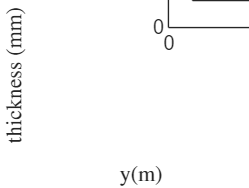



figure(4)
clf;
plot(wing_opt.stripy(wingidx),t_FS(wingidx)*1000,'r')
hold on
plot(wing_opt.stripy(wingidx),t_RS(wingidx)*1000,'Color', [0 0.4470 0.7410])
hold on
plot(wing_opt.stripy(wingidx),wb.tF(wingidx)*1000,'r--','LineWidth',1.5)
hold on
plot(wing_opt.stripy(wingidx),wb.tR(wingidx)*1000, 'Color', [0 0.4470 0.7410], 'LineStyle', '--', 'LineWidth', 1.5)
legend("Front spar ideal","Rear spar ideal", "Front spar","Rear spar","Location","SouthWest","Interpreter", "latex")
xlim([0, wing_opt.b/2]);
xlabel("y(m)", "Interpreter", "latex")
ylabel("thickness (mm)", "Interpreter", "latex")
ylim([0 0.022*1000])
print(gcf, fullfile('images_new', 'tspar.png'), '-dpng', '-r300');


t_sFS = ts_t * wb.tF;
t_sRS = ts_t * wb.tR;

%hs = (1.672 a t)/(1.6 ts)
h_sFS = (As_bt.*wb.a.*wb.tF)./(1.6.*t_sFS)

h_sFS =     0.0615    0.0615    0.0615    0.0615    0.0615    0.0634    0.0634    0.0634    0.0634    0.0634    0.0653    0.0653    0.0653    0.0653    0.0653    0.0673    0.0673    0.0673    0.0673    0.0673    0.0693    0.0693    0.0693    0.0693    0.0693    0.0715    0.0715    0.0715    0.0715    0.0715    0.0736    0.0736    0.0736    0.0736    0.0736    0.0759    0.0759    0.0759    0.0759    0.0759    0.0759    0.0782    0.0782    0.0782    0.0782    0.0782    0.0782    0.0806    0.0806    0.0806


h_sRS = (As_bt.*wb.a.*wb.tR)./(1.6.*t_sRS)

h_sRS =     0.0615    0.0615    0.0615    0.0615    0.0615    0.0634    0.0634    0.0634    0.0634    0.0634    0.0653    0.0653    0.0653    0.0653    0.0653    0.0673    0.0673    0.0673    0.0673    0.0673    0.0693    0.0693    0.0693    0.0693    0.0693    0.0715    0.0715    0.0715    0.0715    0.0715    0.0736    0.0736    0.0736    0.0736    0.0736    0.0759    0.0759    0.0759    0.0759    0.0759    0.0759    0.0782    0.0782    0.0782    0.0782    0.0782    0.0782    0.0806    0.0806    0.0806


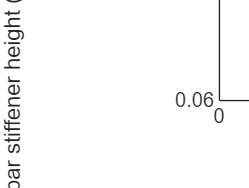

figure(5)
clf;
scatter(wing_opt.stripy(sparidx), h_sFS(sparidx))
ylabel("spar stiffener height (m)")
xlim([0 wing_opt.b/2])
print(gcf, fullfile('images_new', 'hss.png'), '-dpng', '-r300');


% %Verify interactive buckling in spar
% %check front spar
% tau_cr = 8.1*E.*(wb.tF./wb.a).^2;
% tau_cr_tresca = 125*1e6;
% tau_0 = qFneg./wb.tF;
% 
% Asbt_spar = t_sFS.*h_sFS*1.6./(wb.a.*t_sFS);
% ts_t_spar = 1.076;
% 
% R_c = interpsr_s0(Asbt_spar,ts_t_spar);
% R_s = tau_cr_tresca/tau_0;

IxFS = 1/12*wb.tF.*(wb.b2_c.*wing_opt.cn).^3;
sigma_cFS = M.*wb.b2_c.*wing_opt.cn/2./IxFS

sigma_cFS = 1.0e+09 *

         0    0.0001    0.0007    0.0019    0.0039    0.0068    0.0106    0.0155    0.0214    0.0285    0.0366    0.0460    0.0565    0.0682    0.0811    0.0952    0.1105    0.1271    0.1448    0.1638    0.1840    0.2053    0.2279    0.2516    0.2765    0.3026    0.3298    0.3582    0.3877    0.4182    0.4499    0.4827    0.5165    0.5514    0.5873    0.6242    0.6621    0.7010    0.7409    0.7817    0.8235    0.8662    0.9098    0.9542    0.9996    1.0457    1.0928    1.1406    1.1893    1.2387



IxRS = 1/12*wb.tR.*(wb.b2_c.*wing_opt.cn).^3;
sigma_cRS = M.*wb.b2_c.*wing_opt.cn/2./IxRS

sigma_cRS = 1.0e+09 *

         0    0.0001    0.0007    0.0019    0.0039    0.0068    0.0106    0.0155    0.0214    0.0285    0.0366    0.0460    0.0565    0.0682    0.0811    0.0952    0.1105    0.1271    0.1448    0.1638    0.1840    0.2053    0.2279    0.2516    0.2765    0.3026    0.3298    0.3582    0.3877    0.4182    0.4499    0.4827    0.5165    0.5514    0.5873    0.6242    0.6621    0.7010    0.7409    0.7817    0.8235    0.8662    0.9098    0.9542    0.9996    1.0457    1.0928    1.1406    1.1893    1.2387


## 4. Dcell

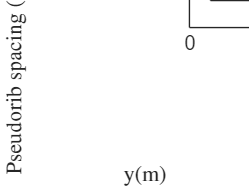

sigmaY = Al7068.sigma_y_tensile;
sigma_yield_tens = Al7068.sigma_y_tensile; % [Pa] From your material data
E = Al7068.E;                              % [Pa] Young’s modulus
b_D = pi * wb.R_c .* wing_opt.cn;          % [m] D-cell circumference (already computed)
[yprib, Nprib] = createRibLocationsFromL(b_D, wing_opt, D);

y_wing = wing_opt.stripy;
yrib   = yprib;

% Sort yrib if not already sorted
yrib = sort(yrib);

% Pre-allocate L
L = zeros(size(y_wing));

for i = 1:length(y_wing)
    y_i = y_wing(i);

    % 1) Check if y_i is within [-D/2, D/2]
    if (y_i >= -D/2) && (y_i <= D/2)
        % If in the fuselage region, set L to NaN
        L(i) = NaN;
    else
        % 2) Otherwise, find the adjacent ribs
        k = find(yrib <= y_i, 1, 'last');

        if isempty(k)
            % y_i < yrib(1)
            L(i) = yrib(2) - yrib(1);
        elseif k == length(yrib)
            % y_i >= yrib(end)
            L(i) = yrib(end) - yrib(end-1);
        else
            % y_i lies between yrib(k) and yrib(k+1)
            L(i) = yrib(k+1) - yrib(k);
        end
    end
end

wb.a_D = L;

figure(1)
clf;
plot(wing_opt.stripy(wingidx),b_D(wingidx),'LineWidth',1.5)
hold on
plot(wing_opt.stripy(wingidx),wb.a_D(wingidx))
legend("Ideal = $b_D$","Actual = $a_D$","Location","SouthWest","Interpreter", "latex")
xlim([0, wing_opt.b/2]);
xlabel("y(m)", "Interpreter", "latex")
ylabel("Pseudorib spacing (m)", "Interpreter", "latex")
print(gcf, fullfile('images_new', 'pseudorib.png'), '-dpng', '-r300');


wb.Nprib =58; 

a_D = wb.a_D;
b_D = pi*wb.R_c.*wing_opt.cn;
R = wb.R_c.*wing_opt.cn;
taumax = sigmaY/2;

%initial guess
t1 = 10e-3*ones(size(wing_opt.stripy));
t2 = 10e-3*ones(size(wing_opt.stripy));
converged = false

converged = logical
   0


iter = 0 

iter = 0

maxiter = 6

maxiter = 6

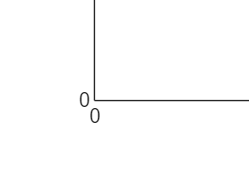

    0.0094



Converged


    0.0093



figure
while converged == false && iter < maxiter
    q_D = [];
    t1 = real(t2);
    for j =1:length(wingidx)
        i = wingidx(j);
        [~, q_D(i)] = shearFlow(wing_opt.cn(i), wb, tau(i), wb.t_Upper(i), wb.t_Lower(i), wb.tF(i), wb.tR(i), t1(i));
        %shear stress = q / t = buckling shear stress
    end
    b_RT = b_D./sqrt(R.*t1);
    b_RT = b_RT(wingidx);
    Ks = [];
    for j =1:length(wingidx)
        i = wingidx(j);
        Ks(i) = interpKspolyfit(R(i),t1(i),a_D(i),b_D(i));
    end
    %t2 = q_D./(Ks.*E.*t1.^2./b_D.^2);
    t2 = b_D.*sqrt((q_D./t1)./(Ks.*E));
    if abs(max(t2) - max(t1)) < 1e-4
        converged = true;
        disp("Converged")
    end
    plot(wing_opt.stripy(wingidx),t2(wingidx)*1000)
    hold on
    iter = iter + 1;
    disp(max(t2))
    %converged = true
end

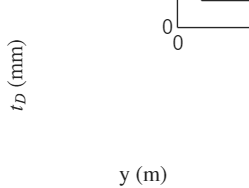

hold on
yline(max(t2)*1000,'--')
xlabel("y (m)","Interpreter","latex")
ylabel("$t_D$ (mm)","Interpreter","latex")
legend("i=1","i=2","i=3","Converged value","Interpreter","Latex","Location","SouthWest")

wb.tD = max(t2);
wb.tr_D = 3e-3;

%print(gcf, fullfile('images_new', 'tD.png'), '-dpng', '-r300');

Interactive Buckling

Verify for upper and lower skin, front and rear spar

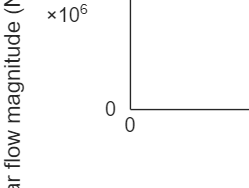

qF = -S./(2.*wb.b2_c.*wing_opt.cn);
qFneg = -Sneg./(2.*wb.b2_c.*wing_opt.cn);



q_wb = [];
q_D = [];
q_wbneg = [];
q_Dneg = [];
for j = 1:length(wingidx)
    i = wingidx(j);
    [q_wb(i), q_D(i)] = shearFlow(wing_opt.cn(i), wb, tau(i), wb.t_Upper(i), wb.t_Lower(i), wb.tF(i), wb.tR(i), wb.tD);
    [q_wbneg(i), q_Dneg(i)] = shearFlow(wing_opt.cn(i), wb, tauneg(i), wb.t_Upper(i), wb.t_Lower(i), wb.tF(i), wb.tR(i), wb.tD);
end



figure(1)
clf;
plot(wing_opt.stripy(wingidx),q_wb(wingidx))
hold on
plot(wing_opt.stripy(wingidx),abs(q_wbneg(wingidx)),'--')
hold on
plot(wing_opt.stripy(wingidx),abs(q_D(wingidx)))
hold on
plot(wing_opt.stripy(wingidx),abs(q_Dneg(wingidx)),'--')
legend("Upper/lower skin, +","Upper/lower skin, -","D-cell, +","D-cell, -")
ylabel("shear flow magnitude (N/m)")
xlim([0 wing_opt.b/2])



%in upper skin, q_wb
RcU = sigma_Uskin./sigmacr_Uskin

RcU =        NaN    0.0083    0.0215    0.0360    0.0517    0.0683    0.0856    0.1033    0.1215    0.1401    0.1589    0.1780    0.1973    0.2168    0.2364    0.2562    0.2760    0.2960    0.3160    0.3360    0.3561    0.3762    0.3964    0.4165    0.4366    0.4567    0.4768    0.4969    0.5170    0.5370    0.5569    0.5768    0.5967    0.6165    0.6363    0.6560    0.6756    0.6952    0.7147    0.7341    0.7535    0.7727    0.7919    0.8111    0.8301    0.8491    0.8680    0.8867    0.9055    0.9241


RsU = q_wb./wb.t_Upper./(sigmaYT./2)

RsU =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0



%in lower skin, q_wb
RcL = sigma_Lskin./sigmacr_Lskin

RcL =        NaN    0.0042    0.0107    0.0180    0.0259    0.0342    0.0428    0.0517    0.0608    0.0700    0.0795    0.0890    0.0987    0.1084    0.1182    0.1281    0.1380    0.1480    0.1580    0.1680    0.1781    0.1881    0.1982    0.2082    0.2183    0.2284    0.2384    0.2485    0.2585    0.2685    0.2785    0.2884    0.2984    0.3083    0.3181    0.3280    0.3378    0.3476    0.3573    0.3671    0.3767    0.3864    0.3960    0.4055    0.4151    0.4245    0.4340    0.4434    0.4527    0.4620


RsL = q_wb./wb.t_Lower./(sigmaYT_L./2)

RsL =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0



xspace = linspace(0,1,100);
figure(2)
clf;
scatter(RcU(wingidx),RsU(wingidx),'x')
hold on
scatter(RcL(wingidx),RsL(wingidx),'.')
hold on
plot(xspace, sqrt(0.99-xspace),'k','LineWidth',1.5)

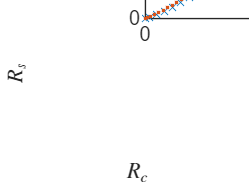

xlabel("$R_c$","Interpreter","latex")
ylabel("$R_s$","Interpreter","latex")
legend("Upper skin","Lower skin","Envelope")

print(gcf, fullfile('images_new', 'Interactive Buckling.png'), '-dpng', '-r300');


%find index that RcU + RsU^2 > 0.99
idx = find(RcU + RsU.^2 > 0.99);
wing_opt.stripy(idx)

ans =     1.9224    1.9936    2.0648    2.1360    2.2072    2.2784    2.3496    2.4208    2.4920    2.5632    2.6344    2.7056    2.7768    2.8480    2.9192    2.9904    3.0616    3.1328    3.2040    3.2752    3.3464    3.4176    3.4888    3.5600    3.6312    3.7024    3.7736    3.8448    3.9160    3.9872    4.0584    4.1296    4.2008    4.2720    4.3432    4.4144    4.4856    4.5568    4.6280    4.6992    4.7704    4.8416    4.9128    4.9840    5.0552    5.1264    5.1976    5.2688    5.3400    5.4112


[Mass_Lskin,M_Lskin,M_Lskin_stringer,thiswb.b1_c_Lower] = LskinMass(rho_Lskin, wing_opt, thiswb, wingidx)

Mass_Lskin = 1.8996e+03

M_Lskin = 696.5633

M_Lskin_stringer = 1.2030e+03

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 … ] (1×301 double)
        t_Lower: [0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5800
           b1_c: [0.0073 0.0072 0.0072 0.0071 0.0071 0.0070 0.0070 0.0069 0.0069 0.0069 0.0068 0.0068 0.0067 0.0067 0.0066 0.0066 0.0066 0.0065 0.0065 0.0064 0.0064 0.0064 0.0063 0.0063 0.0063 0.0062 0.0062 0.0062 0.0061 0.0061 0.0061 … ] (1×301 double)
     b1_c_Lower: [0.0145 0.0144 0.0143 0.0142 0.0142 0.014

[Mass_Uskin,M_Uskin,M_Uskin_stringer,thiswb.b1_c] = UskinMass(rho_Uskin, wing_opt, thiswb, wingidx)

Mass_Uskin = 960.9812

M_Uskin = 333.0702

M_Uskin_stringer = 627.9110

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 1.0000e-03 … ] (1×301 double)
        t_Lower: [0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 0.0020 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5800
           b1_c: [0.0073 0.0072 0.0072 0.0071 0.0071 0.0070 0.0070 0.0069 0.0069 0.0069 0.0068 0.0068 0.0067 0.0067 0.0066 0.0066 0.0066 0.0065 0.0065 0.0064 0.0064 0.0064 0.0063 0.0063 0.0063 0.0062 0.0062 0.0062 0.0061 0.0061 0.0061 … ] (1×301 double)
     b1_c_Lower: [0.0145 0.0144 0.0143 0.0142 0.0142 0.014



M_Uskin

M_Uskin = 333.0702

M_Uskin_stringer

M_Uskin_stringer = 627.9110

Mass_Uskin

Mass_Uskin = 960.9812


M_Lskin

M_Lskin = 696.5633

M_Lskin_stringer

M_Lskin_stringer = 1.2030e+03

Mass_Lskin

Mass_Lskin = 1.8996e+03


Mrib = ribMass(thiswb, wing_opt, rho_r)

Mrib = 1.7220e+03


%4. front spar
ywing = wing_opt.stripy(wingidx);
tFwing = wb.tF(wingidx);
hF = [];
for i = 1:length(ywing)
    hF(i) = wb.b2_c.*wing_opt.c_at_y(ywing(i));
end
V_FS = trapz(ywing, hF.*tFwing)*2;
As_FS = h_sFS(wingidx).*t_sFS(wingidx).*(1 + 0.3*2);
V_FS_skin = V_FS;
V_FS_stiffeners =  trapz(ywing,As_FS)*2;
V_FS = V_FS  +V_FS_stiffeners;
MFS_stiffeners = V_FS_stiffeners*Al7068.rho;
MFS = V_FS*Al7068.rho

MFS = 438.7604

MFS_total = V_FS*Al7068.rho

MFS_total = 438.7604



%5. rear spar
tRwing = wb.tR(wingidx);
V_RS = trapz(ywing, hF.*tRwing);
As_RS = h_sRS(wingidx).*t_sRS(wingidx).*(1 + 0.3*2);
V_RS_skin = V_RS;
V_RS_stiffeners =  trapz(ywing,As_RS)*2;
V_RS = V_RS  +V_RS_stiffeners;
MRS_stiffeners = V_RS_stiffeners*Al7068.rho

MRS_stiffeners = 112.3009

MRS = V_RS*Al7068.rho

MRS = 275.5306

MRS_total = V_RS*Al7068.rho

MRS_total = 275.5306


%6. D cell
V_D = trapz(ywing, wb.tD.*pi.*wb.R_c.*wing_opt.cn(wingidx))*2;
V_Dr = sum(wb.tr_D.*1/2.*pi*(wb.R_c.*wing_opt.cn(wingidx)).^2)*2;
V_D_total = V_D + V_Dr;
MD = V_D*Al7068.rho

MD = 329.1098

MD_pr = V_Dr*Al7068.rho

MD_pr = 174.8583

MD_total = V_D_total*Al7068.rho

MD_total = 503.9682


total = Mass_Uskin + Mass_Lskin + Mrib + MFS_total + MRS_total + MD_total

total = 5.8008e+03

M_Uskin.*Al7068.price

ans = 1.2024e+03

M_Uskin_stringer.*Al7068.price

ans = 2.2668e+03



M_Lskin.*Al2024.price

ans = 1.3095e+03

M_Lskin_stringer.*Al2024.price

ans = 2.2617e+03


Mrib.*Al7068.price

ans = 6.2162e+03


MFS_stiffeners.*Al7068.price

ans = 405.4062

MFS.*Al7068.price

ans = 1.5839e+03


MRS_stiffeners.*Al7068.price

ans = 405.4062

MRS.*Al7068.price

ans = 994.6656


MD.*Al7068.price

ans = 1.1881e+03

MD_pr.*Al7068.price

ans = 631.2385